## 0. Initializing Variables and  Setting Functions

clear; 
clc; 
fs =1000; % Number of samples per sec
dur = 1; %Signal duration in seconds
fm = 5; %Multiplier for Frequency of Sine Wave in Hz 
snr = 20;
poison_ratio = 0.2;
function plotSig(t, signal,color, mainTitle, xTityle, yTitle, new_legend)
    plot(t, signal, color,'LineWidth', 1.5);
    title(mainTitle);
    xlabel(xTityle);
    ylabel(yTitle);
    legend(new_legend);
    grid on;
end

function cSum = getChkSum(signal) % Get signal's integrity value
    cSum = sum(signal);  
end

## 1: Generation of Clean Wireless Signal

The first section involves generating a simple wireless signal to simulate a  real world wireless situation. The signal created is a 5 Hz frequency sine wave representing the communication signal. 

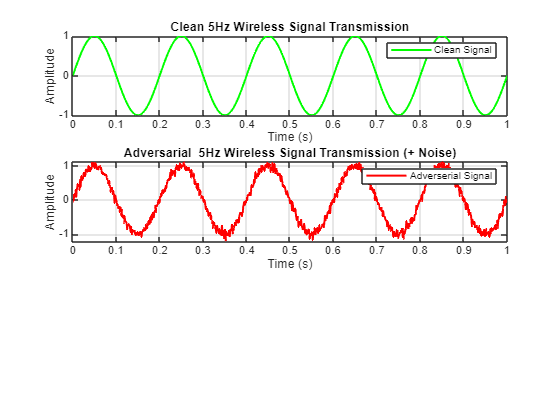

t = linspace(0, dur, fs );  % Time range for signal (0 to 1 sec)
clean_signal = sin(2*pi *fm* t);  % Generate main sine wave

adverserial_signal = awgn(clean_signal, snr, 'measured');  % Generate adverserial signal (clean signal + Gaussian noise)

figure;
subplot(3,1,1);
plotSig(t, clean_signal, 'g', 'Clean 5Hz Wireless Signal Transmission', 'Time (s)' , 'Amplitude', 'Clean Signal');

subplot(3,1,2);
plotSig(t, adverserial_signal, 'r' , 'Adversarial  5Hz Wireless Signal Transmission (+ Noise)','Time (s)', 'Amplitude', 'Adverserial Signal');

## 2. Checksum calculation 

clean_cSum = getChkSum(clean_signal);    % Checksum of clean signal
adverserial_cSum = getChkSum(adverserial_signal);  %Get Checksum by suming signal values

fprintf('Checksum of Clean Signal: %.2f\n', clean_cSum);

Checksum of Clean Signal: 0.00


fprintf('Checksum of Adverserial Signal: %.2f\n', adverserial_cSum);

Checksum of Adverserial Signal: -1.02


## 3. Training the Machine Learning Classification Model

This section trains a Support Vector Machine model to distinguish between clean and adversarial signals, being trained on the first modules’ signal datasets evaluating the SVM's ability to detect adversarial noise.

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |      0.5185 |      2.4925 |      0.5185 |      0.5185 |    0.0013042 |       233.34 |         true |
|    2 | Best   |       0.504 |       34.03 |       0.504 |     0.50473 |       407.81 |     0.015752 |         true |
|    3 | Accept |      0.5155 |      3.4693 |       0.504 |       0.504 |    0.0067942 |    0.0025364 |         true |
|    4 | Accept |       0.516 |      0.1895 |       0.504 |       0.504 |    0.0035582 |      0.12041 |        false |
|    5 | Accept |      0.5185 |     0.25904 |   

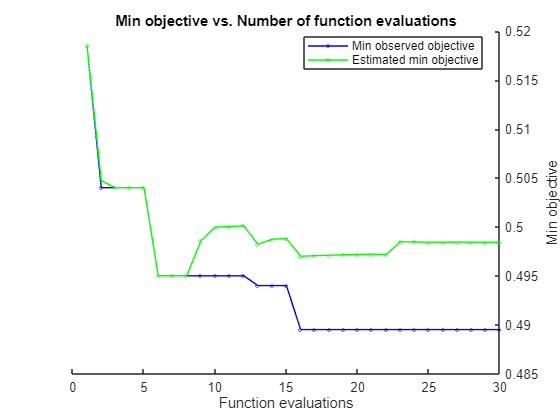

% Add clean & adverserial signals together
X = [clean_signal'; adverserial_signal'];  % Every change every row for amplitude value

% Add labels to distingush signals (1 = clean , 0 = adverserial)
labels = [ones(fs, 1 ); zeros(fs,1 )];  % 1000 clean samples (1) + 1000 adverserial samples (0)


SVMModel = fitcsvm(X, labels, 'KernelFunction', 'linear',...  %Train SVM model & limit to 30 iterations
'Standardize',true, 'ClassNames',[0, 1], ...
'OptimizeHyperparameters','auto', 'HyperparameterOptimizationOptions',struct('MaxObjectiveEvaluations', 30,'kfold', 5));% Use 5-fold cross -validation while automatically adjusting parameters

## 4. Adverserial Attack Detection

This section aims to predict added noise to wireless signals using the previously generated SVM model 

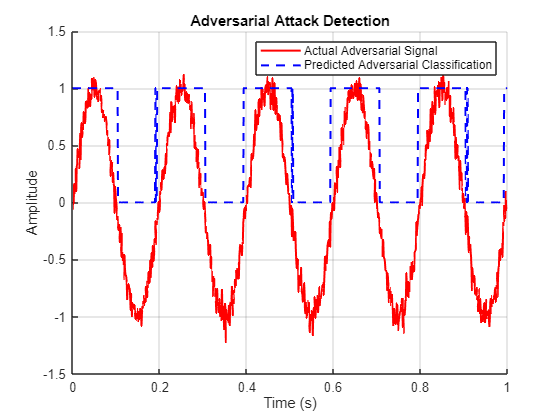

adv_pred = predict(SVMModel ,adverserial_signal'); % Deploy SVM model on the adverserial signal

% Run performance benchmarks for adverserial signal classification
true_adv_labels = zeros(fs, 1);  % True labels for the adverserial signal
prec_adv = sum(adv_pred ==0 & true_adv_labels ==0) / sum(adv_pred ==0);
recall_adv= sum(adv_pred ==0 & true_adv_labels ==0) / sum(true_adv_labels == 0);
f1_adv = 2 * (prec_adv *recall_adv ) / (prec_adv + recall_adv);
figure 
hold on;
plot(t,adverserial_signal,'r', 'LineWidth',1.5);  % Graph actual adversarial signal
plot(t, adv_pred, 'b--', 'LineWidth',1.5);  % Graph predicted adverserial signal
hold off;

title('Adversarial Attack Detection');
xlabel('Time (s)') ;
ylabel('Amplitude');
legend('Actual Adversarial Signal' , 'Predicted Adversarial Classification');
grid on;


fprintf('Adverserial Attack Detection - Precision: %.2f\n',prec_adv);

Adverserial Attack Detection - Precision: 1.00


fprintf('Adverserial Attack Detection - Recall: %.2f\n', recall_adv );

Adverserial Attack Detection - Recall: 0.44


fprintf('Adverserial Attack Detection - F1 Score: %.2f\n',f1_adv);

Adverserial Attack Detection - F1 Score: 0.61


fprintf('Checksum of Adverserial Signal: %.2f\n', adverserial_cSum);

Checksum of Adverserial Signal: -1.02


## 5. Data Poisoning Attack

In this module, we assess the models’ resistance to data poisoning attack, this is accomplished by changing the value of clean signal labels to emulate the effects of data poisoning. The code intentionally poisons 20% of the dataset, flipping bits from 1 to 0 and retraining the support vector machine model based on the poisoned dataset

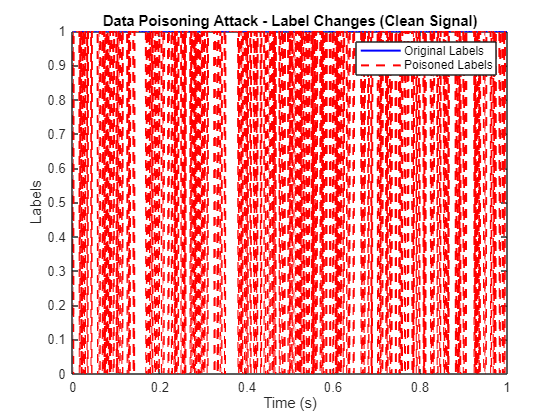


% Poison a portion of the clean signal data to corrupt the training set
poison_count = round(poison_ratio * fs);  % No of poisoned samples
poison_idx = randperm(fs, poison_count);  % Randomly select samples to poison

% Poison the labels by flipping them
poisoned_labels = labels;
poisoned_labels(poison_idx) = 0;  % Poison some of the clean signal labels (flipping them to 0)

% Retrain the SVM model with the poisoned dataset
svmPoisonedModel = fitcsvm(X, poisoned_labels, 'KernelFunction', 'linear', 'Standardize', true, 'ClassNames', [0, 1]);

% Test on the clean signal after poisoning
poisoned_predictions = predict(svmPoisonedModel, X);

% Calculate accuracy for the poisoned model
accuracy_poisoned = sum(poisoned_predictions == labels) / length(labels) * 100;

% Calculate Checksum for the poisoned labels
poisoned_cSum = getChkSum(poisoned_labels);


plot(t, labels(1:fs), 'b', 'LineWidth', 1.5); hold on;
plot(t, poisoned_labels(1:fs), 'r--', 'LineWidth', 1.5);  % Only plot the clean signal part
hold off;
title('Data Poisoning Attack - Label Changes (Clean Signal)');
legend('Original Labels', 'Poisoned Labels');
xlabel('Time (s)');
ylabel('Labels');

fprintf('Accuracy of SVM after Data Poisoning: %.2f%%\n', accuracy_poisoned);

Accuracy of SVM after Data Poisoning: 50.00%


fprintf('Checksum of Poisoned Labels: %.2f\n', poisoned_cSum);

Checksum of Poisoned Labels: 800.00


## 6. Anomaly Detection

This section demonstrates how machine learning can be used for finding anomalies in wireless transmissions, the aim of the code is find whether signal is free of anomlies (clean) or has anomalies.

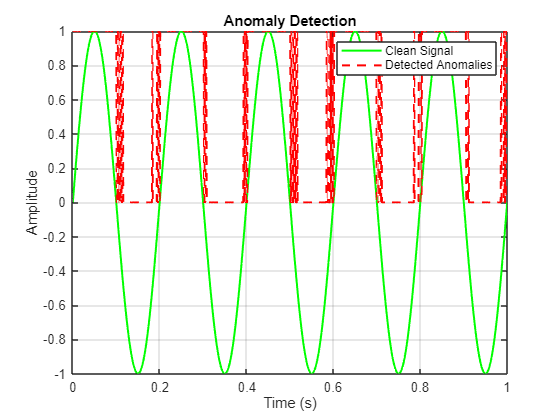

% Generate noisy test signal for anomaly detection
test_signal = clean_signal + 0.18 * randn(1, fs);  % Add random noise
test_signal = test_signal';  % Reshape for SVM

% Predict anomalies using the trained SVM model
anomaly_pred = predict(SVMModel, test_signal);

% Calculate Checksum for the test signal
test_signal_cSum = getChkSum(test_signal);

% Evaluate anomaly detection performance vs original clean labels)
true_labels = ones(fs, 1);  % True labels for the test signal (all clean)
prec_anomaly = sum(anomaly_pred == 1 & true_labels == 1) / sum(anomaly_pred == 1); % Precision score
recall_anomaly = sum(anomaly_pred == 1 & true_labels == 1) / sum(true_labels == 1); % Recall score
f1_anomaly = 2 * (prec_anomaly * recall_anomaly) / (prec_anomaly + recall_anomaly); % F1 Score

figure;
plot(t, clean_signal, 'g', 'LineWidth', 1.5); hold on;
plot(t, anomaly_pred(1:fs), 'r--', 'LineWidth', 1.5);  % Only plot the clean signal region
title('Anomaly Detection');
legend('Clean Signal', 'Detected Anomalies');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;



fprintf('Anomaly Detection: Precision: %.2f\n', prec_anomaly);

Anomaly Detection: Precision: 1.00


fprintf('Anomaly Detection: Recall: %.2f\n', recall_anomaly);

Anomaly Detection: Recall: 0.55


fprintf('Anomaly Detection: F1 Score: %.2f\n', f1_anomaly);

Anomaly Detection: F1 Score: 0.71


fprintf('Checksum of Test Signal: %.2f\n', test_signal_cSum);

Checksum of Test Signal: 2.62
